## Notch Filter implementation of the ECG signal filter

#### Import signal and plot the first second

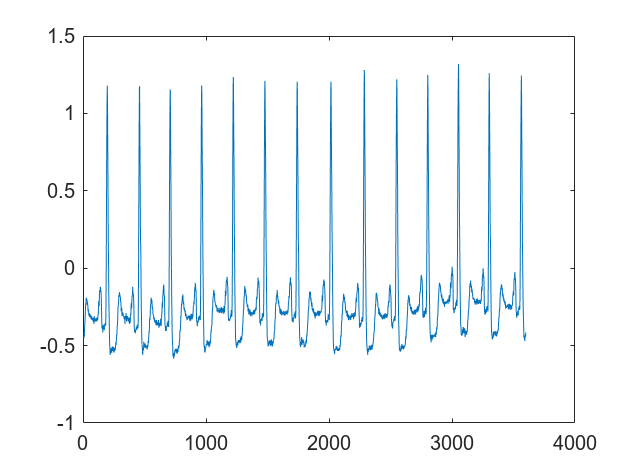

[sig, Fs, tm] = rdsamp('mitdb/105', 1);
signal = sig(1:3600);
plot(signal);

#### **Obtain Fourier Transform**

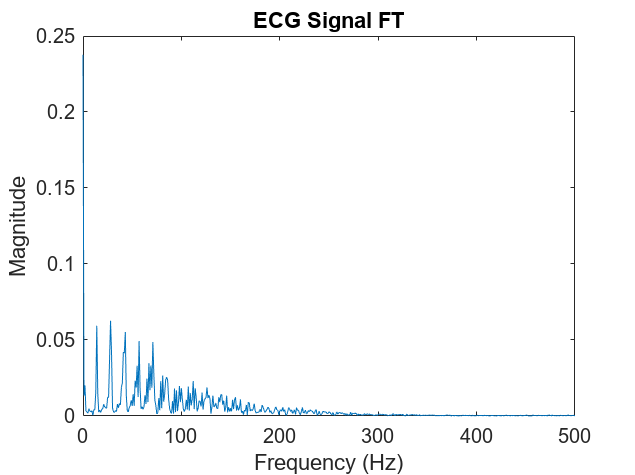

N = 3600;
T = 1/Fs;
sig_fft = fft(signal);
sig_fft_magnitude = abs(fftshift(sig_fft)) / N;    % Magnitude of the FFT
frequencies = (-N/2:N/2-1);      % Frequency axis

figure
plot(frequencies, sig_fft_magnitude);
title('ECG Signal FT')
xlabel('Frequency (Hz)')
ylabel('Magnitude')
xlim([0,500])

Generate noise signal

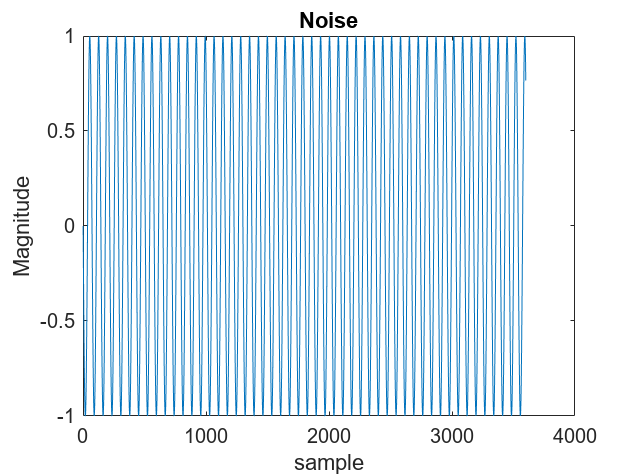


noise_t = linspace(1,T,N);
noise = 1*sin(2*pi*50*noise_t); 
figure
plot(noise)
xlabel('sample')
ylabel('Magnitude')
title('Noise')

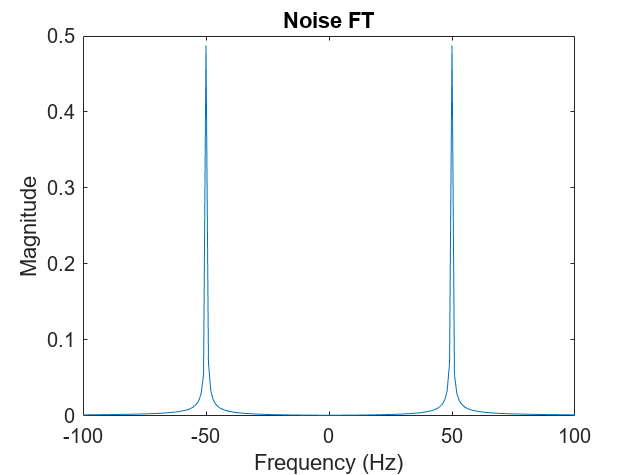



% Compute the FFT
noise_fft = fft(noise);               % Perform the FFT
noise_fft_magnitude = abs(fftshift(noise_fft)) / N;    % Magnitude of the FFT
figure
plot(frequencies, noise_fft_magnitude);
title('Noise FT')
xlabel('Frequency (Hz)')
ylabel('Magnitude')
xlim([-100,100])

Add noise to the original signal

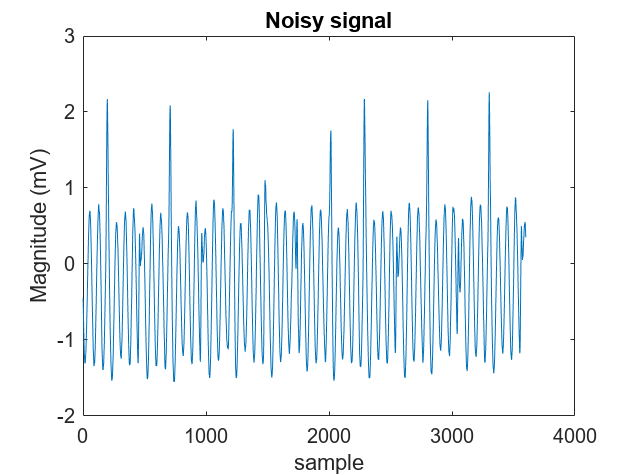

noisy_signal = signal+transpose(noise);
figure
plot(noisy_signal)
xlabel('sample')
ylabel('Magnitude (mV)')
title('Noisy signal')

Find FFT of noisy signal

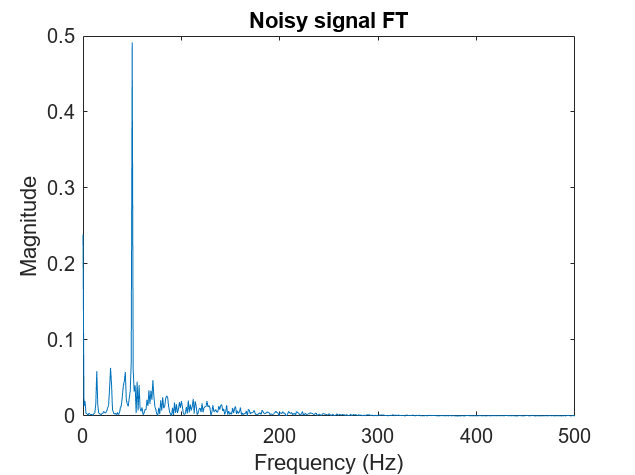

noisy_signal_fft = fft(noisy_signal);               % Perform the FFT
noisy_signal_fft_magnitude = abs(fftshift(noisy_signal_fft)) / N;    % Magnitude of the FFT
figure
plot(frequencies, noisy_signal_fft_magnitude);
title('Noisy signal FT')
xlabel('Frequency (Hz)')
ylabel('Magnitude')
xlim([0,500])

### Notch filter

t = (0:1/Fs:10-1/Fs)'; % Time vector for 1 second
F0 = 50; % Frequency to remove
BW = 2; % Desired bandwidth of the notch in Hz

% Design a notch filter using designfilt
notchFilter = designfilt('bandstopiir', ...
    'FilterOrder', 2, ...
    'HalfPowerFrequency1', F0 - BW/2, ...
    'HalfPowerFrequency2', F0 + BW/2, ...
    'DesignMethod', 'butter', ...
    'SampleRate', Fs);

apply filter

% Assuming 'signal' is your ECG data
e_notch = filtfilt(notchFilter, noisy_signal);

compare with original signal in time domain:

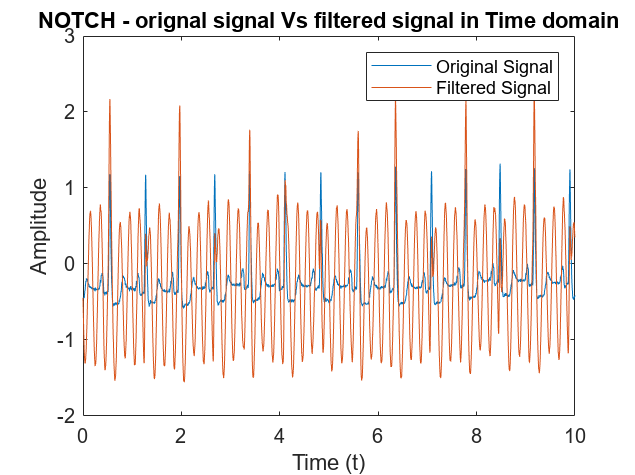

figure;
plot(t, [signal, e_notch]);
title("NOTCH - orignal signal Vs filtered signal in Time domain")
legend('Original Signal',  'Filtered Signal');
xlabel('Time (t)');
ylabel('Amplitude');

now repeat comparison in frequency domain

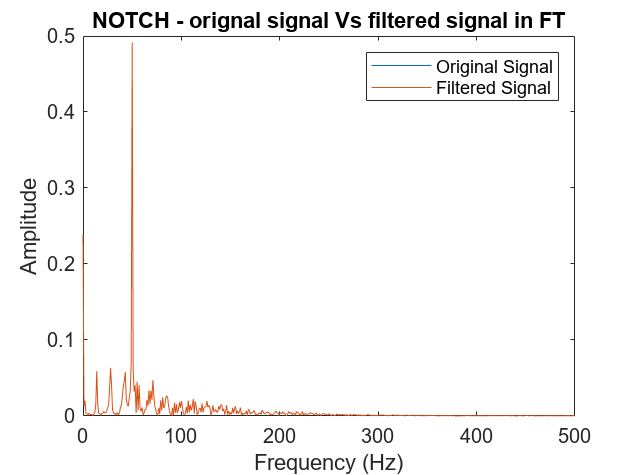

notch_fft = fft(e_notch);               % Perform the FFT
notch_fft_magnitude = abs(fftshift(notch_fft)) / N; 

figure;
plot(frequencies, [noisy_signal_fft_magnitude, notch_fft_magnitude]);
title("NOTCH - orignal signal Vs filtered signal in FT")
legend('Original Signal',  'Filtered Signal');
xlabel('Frequency (Hz)');
ylabel('Amplitude');
xlim([0,500])

### LMS implementation

The following fields will be used by all adaptive filters

mu = 0.01; % Learning rate (step size)
filter_len = 32; % Filter length
delay = 8; % Delay in samples, roughly corresponding to one period of 50Hz noise at Fs=360Hz
reference_signal = transpose(noise);%[zeros(delay, 1); noisy_signal(1:end-delay)];

Lms Implementation:

lms = dsp.LMSFilter('Length', filter_len, 'StepSize', mu, 'Method', 'LMS');
[y_lms, e_lms] = lms(reference_signal, noisy_signal);

compare with original signal in time domain:

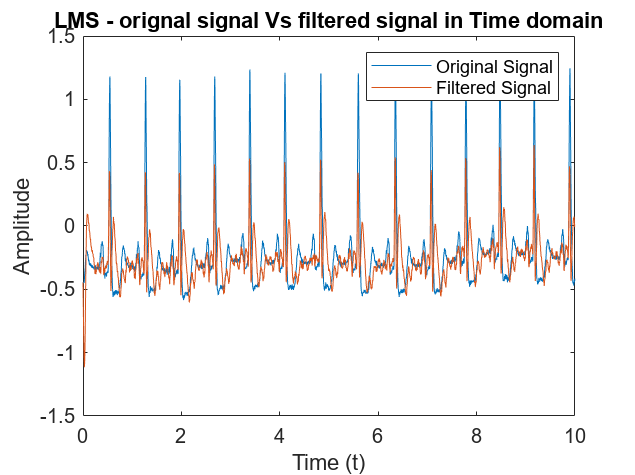

figure;
plot(t, [signal, e_lms]);
title("LMS - orignal signal Vs filtered signal in Time domain")
legend('Original Signal',  'Filtered Signal');
xlabel('Time (t)');
ylabel('Amplitude');

now repeat comparison in frequency domain

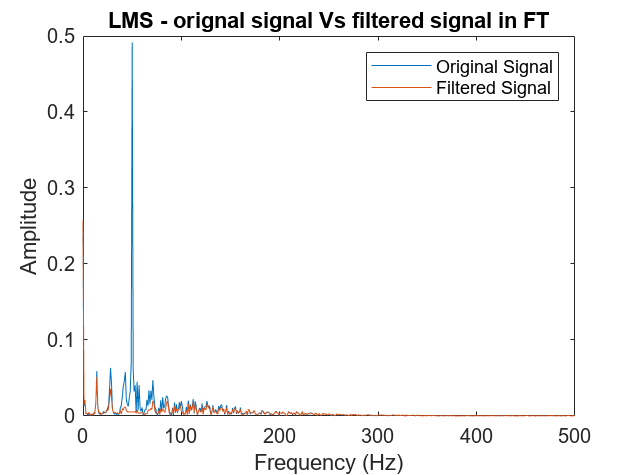

lms_fft = fft(e_lms);               % Perform the FFT
lms_fft_magnitude = abs(fftshift(lms_fft)) / N; 

figure;
plot(frequencies, [noisy_signal_fft_magnitude, lms_fft_magnitude]);
title("LMS - orignal signal Vs filtered signal in FT")
legend('Original Signal',  'Filtered Signal');
xlabel('Frequency (Hz)');
ylabel('Amplitude');
xlim([0,500])

Calculate statistics

lms_SNR = calculate_SNR(signal, e_lms);
lms_PRD = calculate_PRD(signal, e_lms);
lms_MSE= calculate_MSE(signal, e_lms);

disp(['lms_SNR = ',num2str(lms_SNR)]);

lms_SNR = -3.3545


disp(['lms_PRD = ',num2str(lms_PRD)]);

lms_PRD = 67.9637


disp(['lms_MSE = ',num2str(lms_MSE)]);

lms_MSE = 0.068024


### Normalized LMS implementation

n_lms = dsp.LMSFilter('Length', filter_len, 'StepSize', mu, 'Method', 'Normalized LMS');
[y_nlms, e_nlms] = n_lms(reference_signal, noisy_signal);

compare with original signal in time domain:

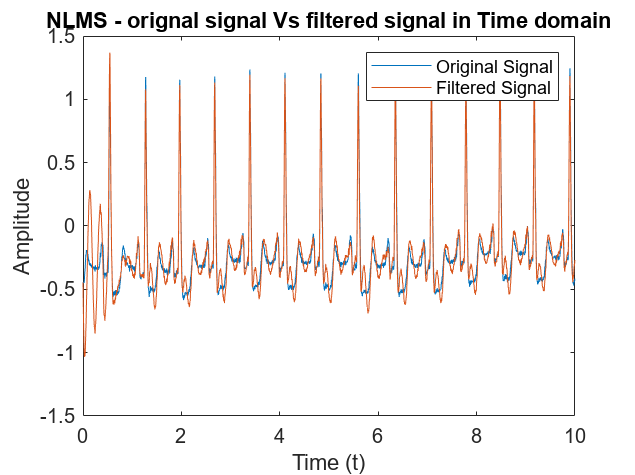

figure;
plot(t, [signal, e_nlms]);
title("NLMS - orignal signal Vs filtered signal in Time domain")
legend('Original Signal',  'Filtered Signal');
xlabel('Time (t)');
ylabel('Amplitude');

now repeat comparison in frequency domain

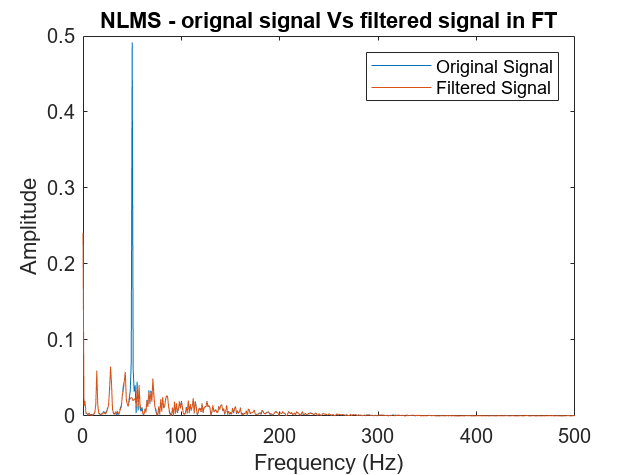

nlms_fft = fft(e_nlms);               % Perform the FFT
nlms_fft_magnitude = abs(fftshift(nlms_fft)) / N; 

figure;
plot(frequencies, [noisy_signal_fft_magnitude, nlms_fft_magnitude]);
title("NLMS - orignal signal Vs filtered signal in FT")
legend('Original Signal',  'Filtered Signal');
xlabel('Frequency (Hz)');
ylabel('Amplitude');
xlim([0,500])

calculate statistics

nlms_SNR = calculate_SNR(signal, e_nlms);
nlms_PRD = calculate_PRD(signal, e_nlms);
nlms_MSE= calculate_MSE(signal, e_nlms);

disp(['lms_SNR = ',num2str(nlms_SNR)]);

lms_SNR = -11.1235


disp(['lms_PRD = ',num2str(nlms_PRD)]);

lms_PRD = 27.7861


disp(['lms_MSE = ',num2str(nlms_MSE)]);

lms_MSE = 0.01137


### RLS implementation

lambda = 0.999; % Forgetting factor
rls = dsp.RLSFilter('Length',filter_len,'ForgettingFactor',lambda);
[y_rls, e_rls] = rls(reference_signal, noisy_signal);

compare with original signal in time domain:

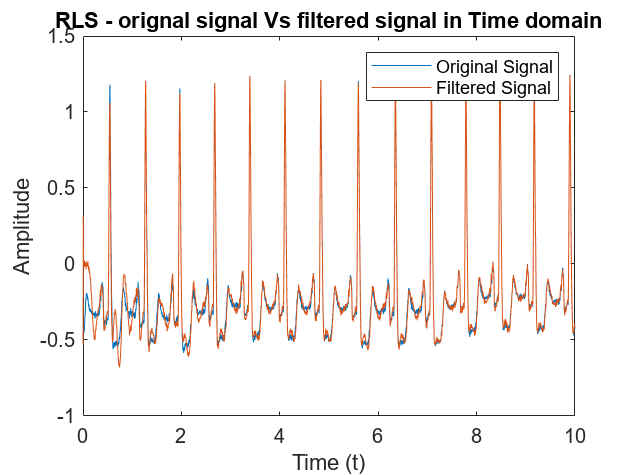

figure;
plot(t, [signal, e_rls]);
title("RLS - orignal signal Vs filtered signal in Time domain")
legend('Original Signal',  'Filtered Signal');
xlabel('Time (t)');
ylabel('Amplitude');

compare with original signal in frequency domain:

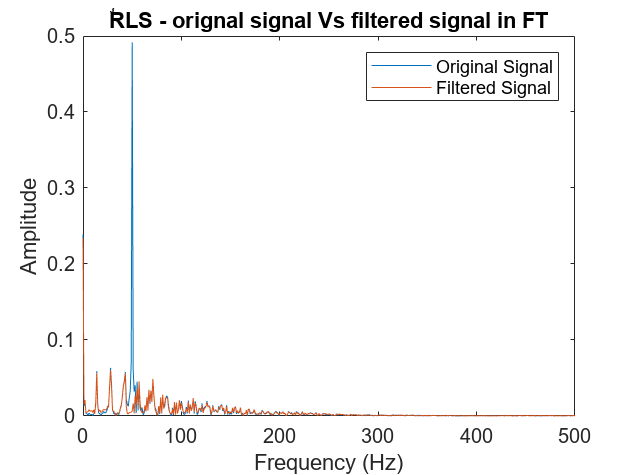

rls_fft = fft(e_rls);               % Perform the FFT
rls_fft_magnitude = abs(fftshift(rls_fft)) / N; 

figure;
plot(frequencies, [noisy_signal_fft_magnitude, rls_fft_magnitude]);
title("ٌRLS - orignal signal Vs filtered signal in FT")
legend('Original Signal',  'Filtered Signal');
xlabel('Frequency (Hz)');
ylabel('Amplitude');
xlim([0,500])

calculate statistics

rls_SNR = calculate_SNR(signal, e_rls);
rls_PRD = calculate_PRD(signal, e_rls);
rls_MSE = calculate_MSE(signal, e_rls);
disp(['rls_SNR = ', num2str(rls_SNR)]);

rls_SNR = -16.8579


disp(['rls_PDR = ', num2str(rls_PRD)]);

rls_PDR = 14.3583


disp(['rls_MSE = ', num2str(rls_MSE)]);

rls_MSE = 0.0030361


### Affine Projection Filter (APA)

apa = dsp.AffineProjectionFilter('Length',filter_len,'StepSize',mu,'ProjectionOrder', 4);
[y_apa, e_apa] = apa(reference_signal, noisy_signal);

compare with original signal in time domain:

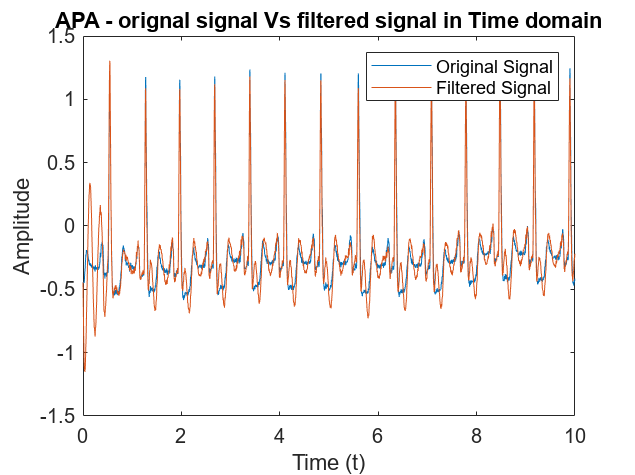

figure;
plot(t, [signal, e_apa]);
title("APA - orignal signal Vs filtered signal in Time domain")
legend('Original Signal',  'Filtered Signal');
xlabel('Time (t)');
ylabel('Amplitude');

compare with original signal in frequency domain:

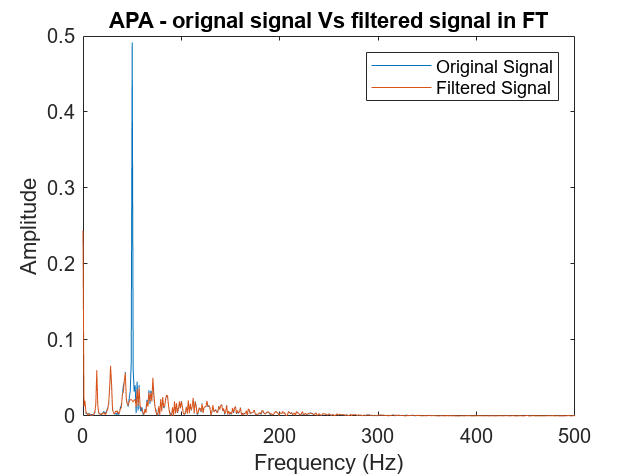

apa_fft = fft(e_apa);               % Perform the FFT
apa_fft_magnitude = abs(fftshift(apa_fft)) / N; 

figure;
plot(frequencies, [noisy_signal_fft_magnitude, apa_fft_magnitude]);
title("APA - orignal signal Vs filtered signal in FT")
legend('Original Signal',  'Filtered Signal');
xlabel('Frequency (Hz)');
ylabel('Amplitude');
xlim([0,500])

calculate statistics

apa_SNR = calculate_SNR(signal, e_apa);
apa_PRD = calculate_PRD(signal, e_apa);
apa_MSE = calculate_MSE(signal, e_apa);
disp(['apa_SNR = ', num2str(apa_SNR)]);

apa_SNR = -9.9211


disp(['apa_PDR = ', num2str(apa_PRD)]);

apa_PDR = 31.9114


disp(['apa_MSE = ', num2str(apa_MSE)]);

apa_MSE = 0.014997
